# **R and Optimal Consumption in Two Periods**

[**Back to Fan's Math for Economist Table of Content**](https://fanwangecon.github.io/Math4Econ/)

We solved previously the consumption problem.

## R is on both Right Hand Side and Left Hand Side of Budget

Given our problem:

- 
$$\max_{c_1, c_2} \log(c_{1}) + \beta \cdot \log(c_{2})$$


- $c_1 > 0$, $c_2 > 0$, 

- 
$$c_2 + (1+r) c_1 \le Z_1 (1+r) + Z_2$$


The price is $r$, how does changing the price impact our choices and "happiness" level?

Stating the problem as we do above makes it very clear that the $r$ is changing the total resources that we have available on the right hand side of the budget constraint, and it is concurrently changing the relative cost of getting $c_2$ vs $c_1$. 

## Changing R and Optimal Choices

We derived [solutions to the optimization problem](https://fanwangecon.github.io/Math4Econ/optimization_application/household_c1_c2_constrained.html) before as a function of r, they were:

beta = 0.90;
z1 = 1;
z2 = 2;
syms r c1 c2 mu
% The Lagrangian
lagrangian = (log(c1) + beta*log(c2)) - mu*( c2 + (1+r)*c1 - z1*(1+r) - z2);
% Given we have many symbols, type K, L, mu at the end to let matlab know what we are solving for
solu = solve(diff(lagrangian, c1)==0, diff(lagrangian, c2)==0, diff(lagrangian, mu)==0, c1, c2, mu, 'Real', true);
solu_c1 = (solu.c1);
solu_c2 = (solu.c2);

At two different interest rate levels, the optimal choices and utility at optimal choices are of course different, we can plot both out graphically following what we did [before](https://fanwangecon.github.io/Math4Econ/optimization_application/household_c1_c2_constrained.html):

% Get Optimal Choices and Utility at Optimal Choices
syms c1
r1 = 0.05;
r2 = 1.05;
c1star_r1 = double(subs(solu_c1, {r}, {r1}));
c1star_r2 = double(subs(solu_c1, {r}, {r2}));
c2star_r1 = double(subs(solu_c2, {r}, {r1}));
c2star_r2 = double(subs(solu_c2, {r}, {r2}));
disp(table(c1star_r1, c1star_r2, c2star_r1, c2star_r2));

    c1star_r1    c1star_r2    c2star_r1    c2star_r2
    _________    _________    _________    _________

     1.5288       1.0398       1.4447       1.9184  



U_at_c_opti_r1 = log(c1star_r1) + beta*log(c2star_r1)

U_at_c_opti_r1 = 0.7556

U_at_c_opti_r2 = log(c1star_r2) + beta*log(c2star_r2)

U_at_c_opti_r2 = 0.6254

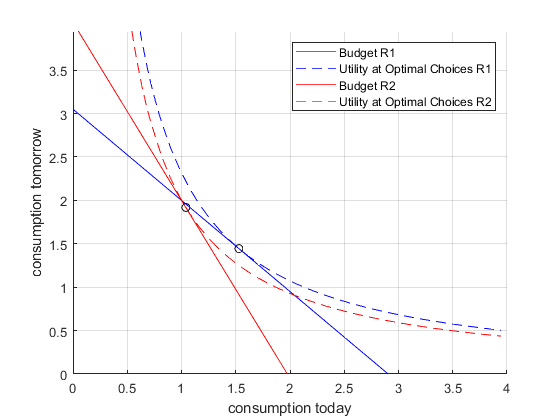


% The Budget Line at r1
f_budget_r1 = z1*(1+r1) + z2 - (1+r1)*c1;
% Indifference at V* at r1
f_indiff_r1 = exp((U_at_c_opti_r1-log(c1))/(beta));

% The Budget Line at r2
f_budget_r2 = z1*(1+r2) + z2 - (1+r2)*c1;
% Indifference at V* at r2
f_indiff_r2 = exp((U_at_c_opti_r2-log(c1))/(beta));

% Graph
figure();
hold on;
% r1
fplot(f_budget_r1, [0, (z1 + z2/(1+r2))*2], 'b');
fplot(f_indiff_r1, [0, (z1 + z2/(1+r2))*2], 'b--');
% r2
fplot(f_budget_r2, [0, (z1 + z2/(1+r2))*2], 'r');
fplot(f_indiff_r2, [0, (z1 + z2/(1+r2))*2], 'r--');
% optmial points
scatter(c1star_r1, c2star_r1, 'k');
scatter(c1star_r2, c2star_r2, 'k');
% legends
ylim([0, (z1 + z2/(1+r2))*2])
xlabel('consumption today');
ylabel('consumption tomorrow');
legend({'Budget R1', 'Utility at Optimal Choices R1',...
        'Budget R2', 'Utility at Optimal Choices R2'})
grid on;

## Substitution Effect

Holding Utility constant, what is the effect of price change?

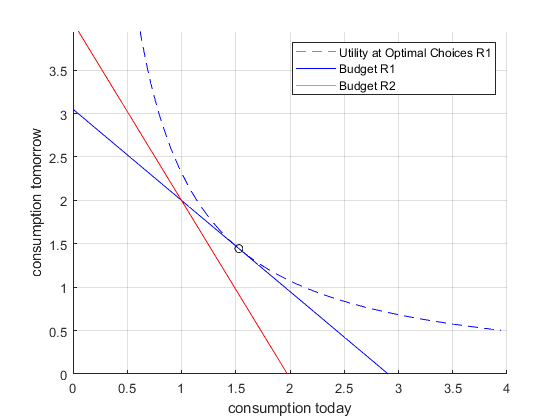

% The Budget Line at r1
f_budget_r1 = z1*(1+r1) + z2 - (1+r1)*c1;
% Indifference at V* at r1
f_indiff_r1 = exp((U_at_c_opti_r1-log(c1))/(beta));

% The Budget Line at r2
f_budget_r2 = z1*(1+r2) + z2 - (1+r2)*c1;

% Graph
figure();
hold on;
% r1
fplot(f_indiff_r1, [0, (z1 + z2/(1+r2))*2], 'b--');
fplot(f_budget_r1, [0, (z1 + z2/(1+r2))*2], 'b');
fplot(f_budget_r2, [0, (z1 + z2/(1+r2))*2], 'r');
% optmial points
scatter(c1star_r1, c2star_r1, 'k');
% legends
ylim([0, (z1 + z2/(1+r2))*2])
xlabel('consumption today');
ylabel('consumption tomorrow');
legend({'Utility at Optimal Choices R1',...
        'Budget R1', 'Budget R2'})
grid on;